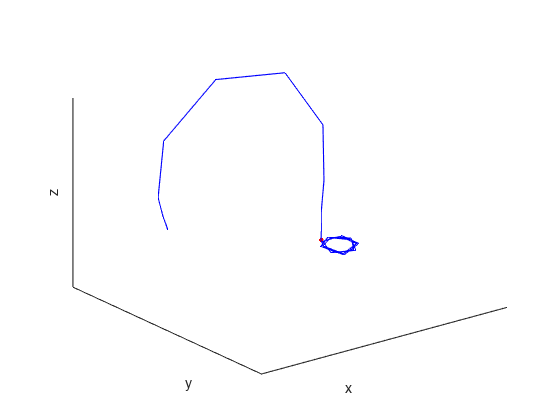

Z=out.data; %%make sure this matches your simulink output name
N=length(Z(:,1));
figure(3);
axHndl = gca;
figNumber = gcf;
hndlList = get(figNumber,"UserData");
set(axHndl, ...
"XLim",[0 50],"YLim",[-20 20],"ZLim",[-30 30], ...
"XTick",[],"YTick",[],"ZTick",[], ...
"SortMethod","childorder", ...
"Visible","on", ...
"NextPlot","add", ...
"View",[-37.5,30], ...
"Clipping","off");

xlabel("x");
ylabel("y");
zlabel("z");

y(1) = Z(1,1);  %%first in x
y(2) = Z(1,2);  %%first in y
y(3) = Z(1,3);  %%first in z

L = 5;

Y = y'*ones(1,L); %%transpose y array to get a 3xL array

cla;
head = line("color","r", "Marker",".","MarkerSize",10,"LineStyle","none","XData",y(1),"YData",y(2),"ZData",y(3));
%% y(3) got cut off in the original code, so added it to line above
body = animatedline("color","b", "LineStyle","-") ;
tail = animatedline("color","b", "LineStyle","-") ;


for j=2:N   
y(1) = Z(j,1);  %%next coordinate in x
y(2) = Z(j,2);  %%next coordinate in y
y(3) = Z(j,3);  %%next coordinate in z

% Update the plot
Y = [y', Y(:,1:L-1)] ; %% transpose the new y again, and add the old Y to the new matrix Y


set(head, "XData", Y(1,1), "YData", Y(2,1), "ZData", Y(3,1));
addpoints(body, Y(1,2), Y(2,2), Y(3,2));
addpoints(tail, Y(1,L), Y(2,L), Y(3,L));
pause(0.1)
% Update the animation every ten steps
    if ~mod(j,10);
   drawnow;
    end
end
